Mathias Bruun Houmøller            -            202006837

# M3NUM1 F15 Reeksamen opgave 3

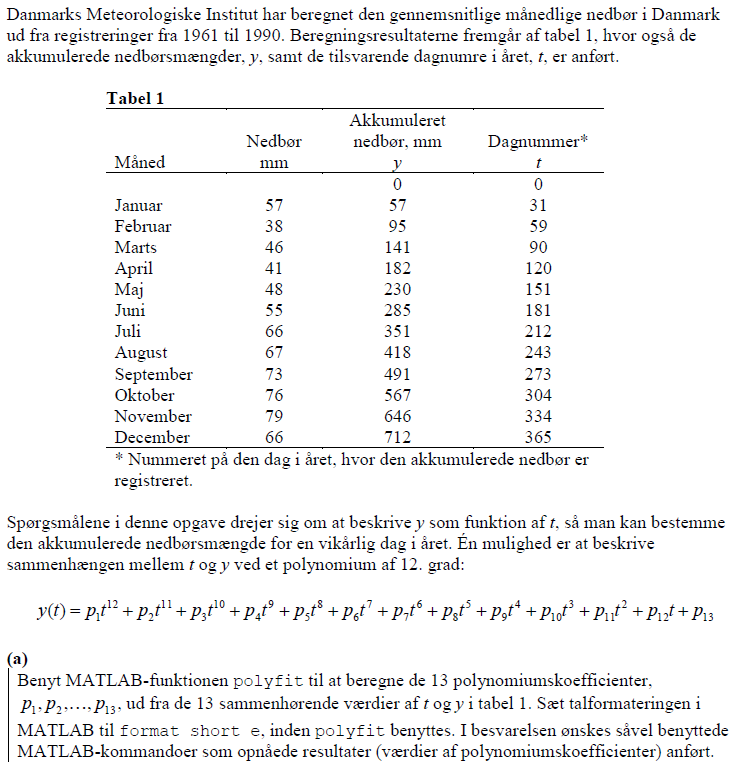

format short e %formater til 4 decimaler i e form
y = [0 57 95 141 182 230 285 351 418 491 567 646 712]'; %data inlæses
x = [0 31 59 90 120 151 181 212 243 273 204 334 365]';
P_fit = polyfit(x,y,12)'; %bruger polyfit til at lave et 12grad polynomie der går igennem alle data punkter

% her vises alle skalarene(p) i tabelen 
T = table(P_fit, x, y);
disp(T)

       P_fit           x             y     
    ___________    __________    __________

    -8.6767e-21    0.0000e+00    0.0000e+00
     1.7866e-17    3.1000e+01    5.7000e+01
    -1.6199e-14    5.9000e+01    9.5000e+01
     8.5173e-12    9.0000e+01    1.4100e+02
    -2.8774e-09    1.2000e+02    1.8200e+02
     6.5364e-07    1.5100e+02    2.3000e+02
    -1.0147e-04    1.8100e+02    2.8500e+02
     1.0710e-02    2.1200e+02    3.5100e+02
    -7.4849e-01    2.4300e+02    4.1800e+02
     3.2713e+01    2.7300e+02    4.9100e+02
    -7.9580e+02    2.0400e+02    5.6700e+02
     8.0388e+03    3.3400e+02    6.4600e+02
    -1.3481e-04    3.6500e+02    7.1200e+02



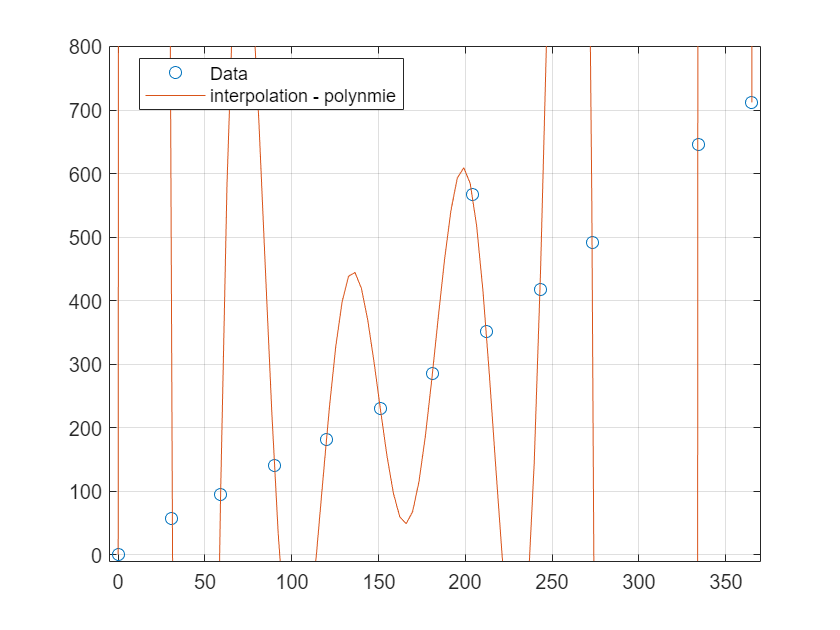

%data en plottes for at se hvordan vores fit ligger
xx = linspace(0,365); %laver 100 værdier ligeligt fordelt fra 0 til 365
yy = polyval(P_fit,xx); %giver de interpolatede y værdier fra xx værdierne
%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data')
hold on
plot(xx,yy, 'DisplayName', 'interpolation - polynmie')
legend('location', 'best')
xlim([-5, 370]) % Plotte begrænses for at fokusere på data punkterne
ylim([-10,800])
grid
hold off

Vi bruger interp1 for at lave interpolation imellem data lineært.

Vi indsæter dag 100

ned_int_100 = interp1(x,y,100,"linear")

ned_int_100 =    1.5467e+02


Således er vores nedbør 155 mm

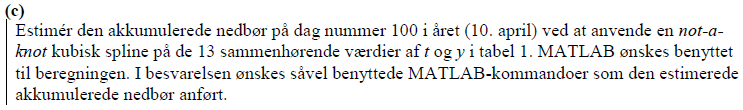

ned_spl_100 = spline(x,y,100) %spline bruges til at lave interpolation imellem værdierne.

ned_spl_100 =    1.5111e+02


Når der er gevet 2 vektor med samme lægnde benyttes not-a-knot metoden i spline.

således fås 151 mm nedbør på dag 100

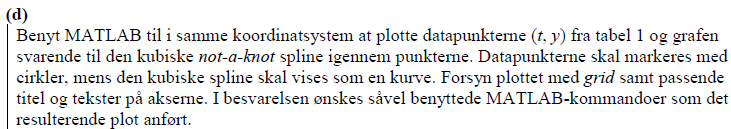

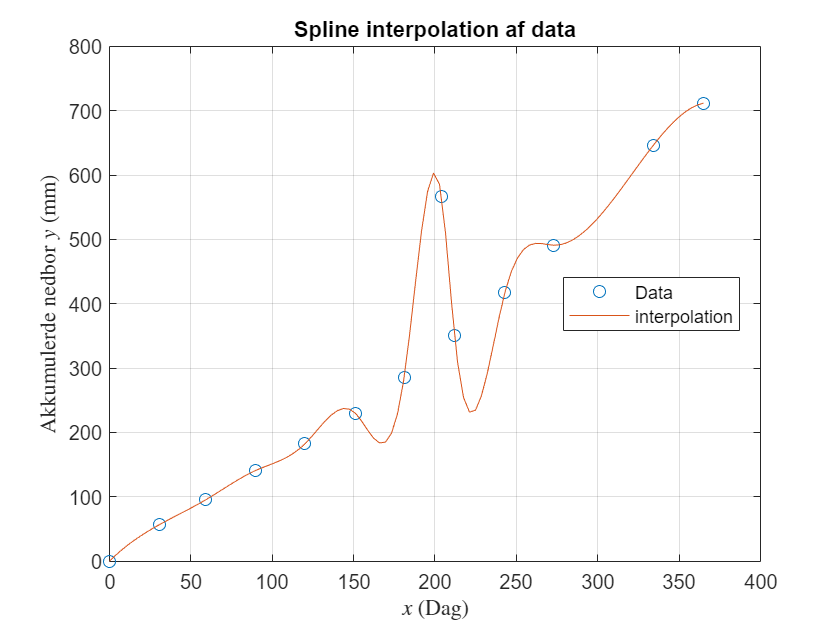

ned_spl_cub = spline(x,y,xx); % der laves igen en interpolation af dataen nu bruges linspacen fra
% tidliger til at danne 100 punkter som kurven kan følge

%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data') %data plottes
hold on
plot(xx,ned_spl_cub, 'DisplayName', 'interpolation') % interpolation med spline plottes

% formalier
legend('location', 'best')
title('Spline interpolation af data')
xlabel('$x$ (Dag)', 'interpreter', 'latex')
ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
grid
hold off

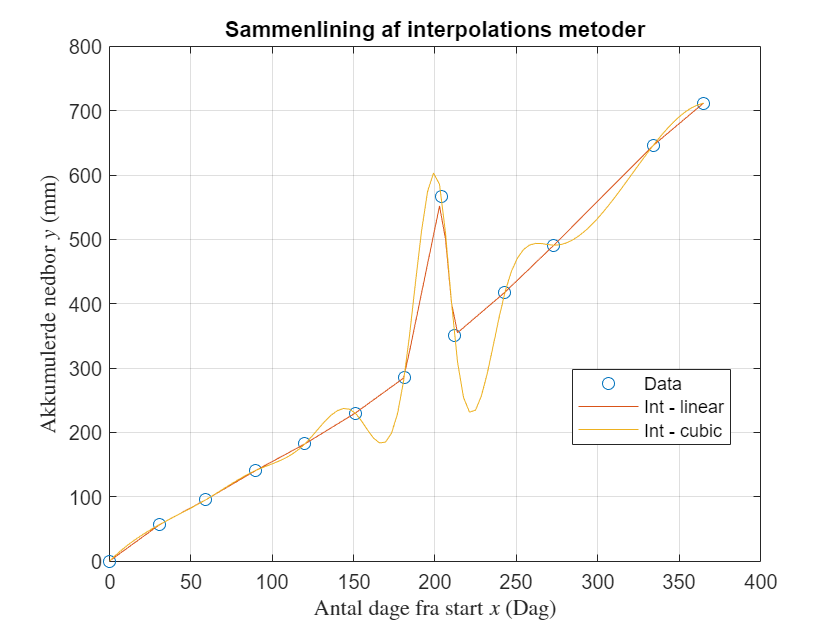

ned_int_lin = interp1(x,y,xx,"linear"); %interpolation interp1 lineær laves med linspacen xx

%der vises begge plot samlede for bedre forståelse
%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data') %data plottes
hold on
% interpolationer plottes
plot(xx,ned_int_lin, 'DisplayName', 'Int - linear') 
plot(xx,ned_spl_cub, 'DisplayName', 'Int - cubic')

% formalier
legend('location', 'best')
title('Sammenlining af interpolations metoder')
xlabel('Antal dage fra start $x$ (Dag)', 'interpreter', 'latex')
ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
grid
hold off

Det ser ud til at være den lineær interpolation der passer bedst i dette tilfælde.

Dette begrundes især med udsvingen i mellem punkt 6 og 7 samt 9 og 11.

Der ses altså et mere linær sammenhæng imellem punkter dog med undtagelse af punkt 8.

Omkring dag 100 hvor vi målte ses også et lille udsving i den cubiske interpolation.

# M3NUM1 E18 Ordinær eksamen opgave 3

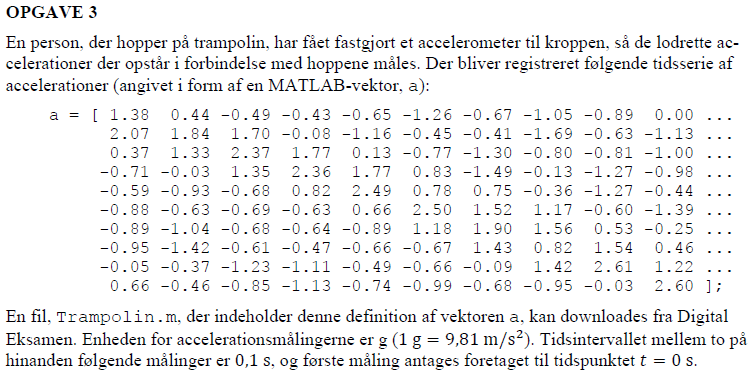

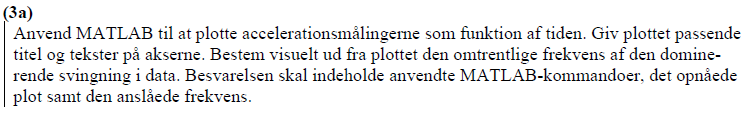

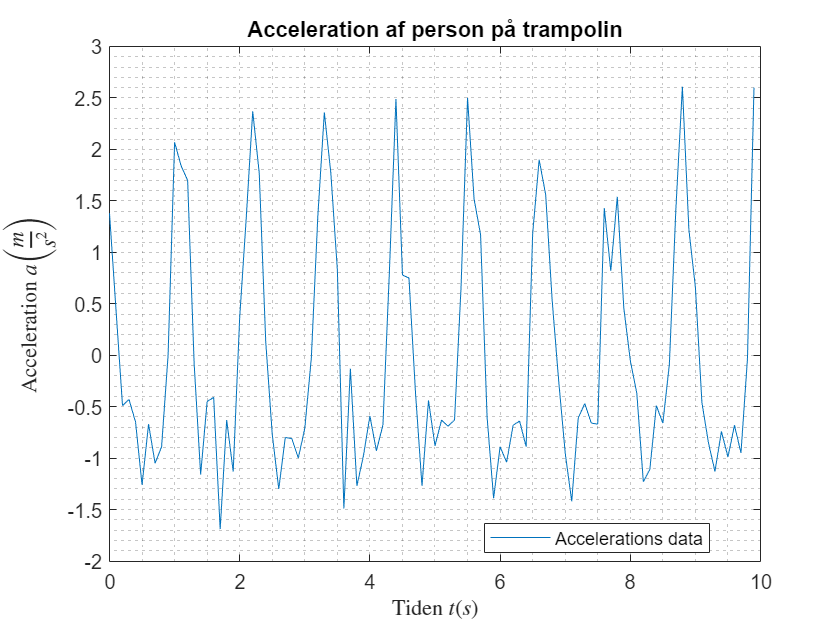

clear
a = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...
2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
-0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...
-0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...
-0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...
-0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...
-0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...
-0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...
0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60 ]; %data for accelerationen

t = 0:0.1:(length(a)/10-0.1); %der laves data for tiden
% her trækkes fra og divideres for at få den rigtige dimention.

figure
plot(t,a, 'DisplayName', 'Accelerations data') %data plottes

% formalier
legend('location', 'best')
title('Acceleration af person på trampolin')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Acceleration $a \left(\frac{m}{s^2}\right)$', 'interpreter', 'latex')
grid('minor')

Der tælles 9 toppe på 10 sekunder således for vi

$f = \frac{9}{10}=0,9 Hz$ for den dominerende svining i plottet

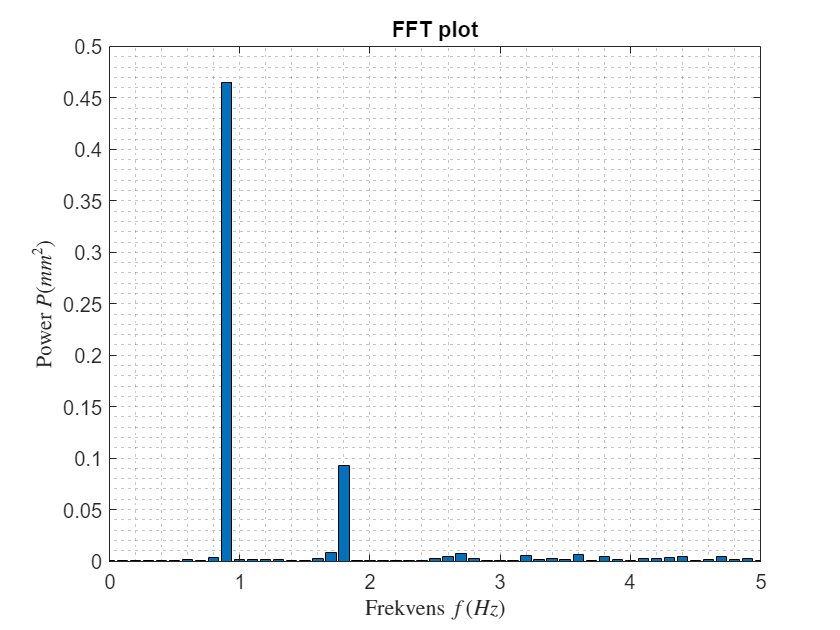

dt = 0.1;                   % Samplingsinterval (s)

n = length(a);              % Antal samplinger % her vælges alt data som sample
T = n*dt;                   % Signallængde (s) % Tiden det tager at køre smplet igennem
A = fft(a)/n;               % FFT af a (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz) %Frekvensen hvormed der tages sampels
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz) % alle frekvensskridt der gennemgåes
P = real(A).^2 + imag(A).^2;% Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
bar(f,P);                   % Plot af powerspektrum %plottes som barplot for bedre overskuelighed
xlim([0 fmax]);             % Afgræns frekvensakse % så der kun ses på et område der ikke gentager en frekvens

% Formalier
title('FFT plot')
xlabel('Frekvens $f(Hz)$', 'interpreter', 'latex')
ylabel('Power $P(mm^2)$', 'interpreter', 'latex')
grid('minor')

result = find(P==max(P)) % vi finder postionen i power vektoren hvor den største frekvens viser sig

result =     10    92


% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Vi kan nu finde frekvensen for det stærkeste signam
f_strong = real(f(10))

f_strong =    9.0000e-01


Signalet findes til $f=0,9Hz$